clc, clear, close all;
addpath OTHER
addpath DATASET

display_points = 1000;
base_sample_rate = 1000;
frame_size = 1001;

# import data

filename_base = 'pianosync.wav';
[y,Fs] = audioread(filename_base); % 8kHz sample
base_sync_1k = SigConToBin(y(:, 1)', Fs, base_sample_rate);
base_sync_1k_base = double(base_sync_1k)-0.5;
base_sync_1k = base_sync_1k_base;

filename_EMG = 'opensignals_000780589b3a_2023-12-19_11-12-23.txt';
data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
emg_sample_rate = 1000;
emg_sync_1k = ReadEMG(data, emg_sample_rate, base_sample_rate);

Align the datapoints

%[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k, base_sample_rate, emg_sync_1k)
[emg_sync_1k, lag_emg] = Align(base_sync_1k, emg_sync_1k);
emg_sync_1k = emg_sync_1k(lag_emg: end);
base_sync_1k = base_sync_1k(lag_emg: end);

Cut to size

min_length = floor(min([length(emg_sync_1k) length(base_sync_1k)]));
emg_sync_1k = emg_sync_1k(1:min_length);
base_sync_1k = base_sync_1k(1:min_length);


Align the beginning

TODO: needs to be included in the Align function

[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
%shift the signal to the correct position
[~, max_start] = max(emg_corr_start);
max_start = floor((frame_size-max_start))+1

max_start =     22


if max_start < 0
    base_sync_1k = base_sync_1k(abs(max_start): end-abs(max_start));
else
    emg_sync_1k = emg_sync_1k(abs(max_start): end-abs(max_start));
end

Cut to size again

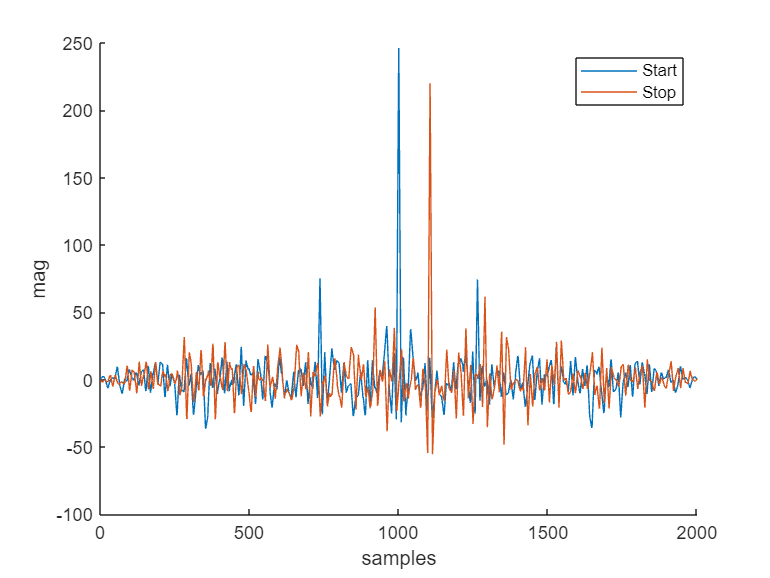

min_length = floor(min([length(emg_sync_1k) length(base_sync_1k)]));
emg_sync_1k = emg_sync_1k(1:min_length);
base_sync_1k = base_sync_1k(1:min_length);

[~, ~] = PlotCorrDrift(frame_size, base_sync_1k, emg_sync_1k)

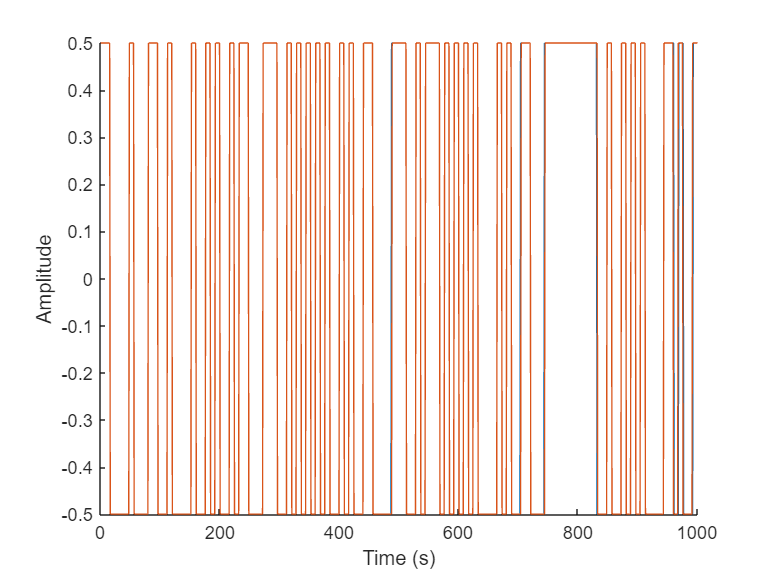


figure;
hold on
plot(base_sync_1k(1:display_points), "DisplayName","base");
plot(emg_sync_1k(1:display_points), "DisplayName","emg");
xlabel('Time (s)');
ylabel('Amplitude');
hold off


format longg

Find the original sample frequency

[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k+0.5, base_sample_rate, emg_sync_1k)

base_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


emg_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


actual_sample_rate =           999.871131648226


[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k, base_sample_rate, emg_sync_1k)

base_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


emg_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


actual_sample_rate =           1000.03068388237


[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k, base_sample_rate, emg_sync_1k)

Error using signal.internal.upfirdn.upfirdnParser
The product of the downsample factor Q and the upsample factor P must be less than 2^31.

Error in upfirdn (line 67)
[x,h,p,q,Lx,Lh,hCols,nChans,outputIsRow] = signal.internal.upfirdn.upfirdnParser(x,h,varargin);

Error in signal.internal.resample.uniformRes

[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
%shift the signal to the correct position
[~, max_start] = max(emg_corr_start);
max_start = floor((frame_size-max_start))+1

cut to size

min_length = floor(min([length(emg_sync_1k) length(base_sync_1k)]))
emg_sync_1k = emg_sync_1k(1:min_length)
base_sync_1k = base_sync_1k(1:min_length)

## Plot

[~, ~] = PlotCorrDrift(frame_size, base_sync_1k, emg_sync_1k)

figure;
hold on
plot(base_sync_1k(end - display_points : end), "DisplayName","base");
plot(emg_sync_1k(end - display_points : end), "DisplayName","emg");
% plot(base_sync_1k(1:display_points), "DisplayName","base");
% plot(emg_sync_1k(1:display_points), "DisplayName","emg");
xlabel('Time (s)');
ylabel('Amplitude');
hold off